# Compute validation metrics for each data-driven model

**Author**: Scott Campit

## Load data

### Load the predicted values for supplementation and deprivation of 100 cancer cell lines from 7 models

% Models are loaded by increasing complexity
clear all
load linearRegression_rescale.mat   % OLS
%load lasso_rescale.mat              % LASSO regression
%load ridge_rescale.mat              % Ridge regression
%load dtr_rescale.mat                % Regression trees
%load rfr_rescale.mat                % Random forest regressor
%load lsboosting_rescale.mat         % Least squares boosting trees
%load snnr.mat               % Shallow neural network regressor

### Load CCLE metadata

The meta data consists of the CCLE cancer cell line, tissue lineage, medium, and cell culture. This will be used for further visualization of the data.

load meta.mat; head(meta, 10)

ans = 10×4 table
      CellLine                     Lineage                          Media             Culture    
    ____________    ______________________________________    _________________    ______________

    {'DMS53'   }    {'Lung'                              }    {'Waymouth'     }    {'Adherent'  }
    {'SW1116'  }    {'Large Intestine'                   }    {'L15'          }    {'Adherent'  }
    {'NCIH1694'}    {'Lung'                              }    {'DMEM-F12 wGln'}    {'Suspension'}
    {'P3HR1'   }    {'Haematopoietic and Lymphoid Tissue'}    {'RPMI'         }    {'Empty'     }
    {'HUT78'   }    {'Haematopoietic and Lymphoid Tissue'}    {'RPMI'         }    {'Empty'     }
    {'HOS'     }    {'Urinary Tract'                     }    {'RPMI'         }    {'Empty'     }
    {'HUNS1'   }    {'Bone'                              }    

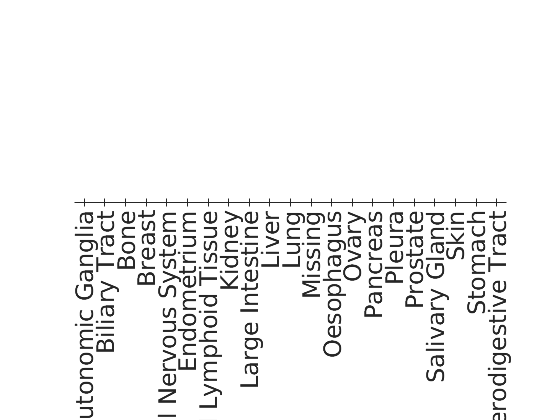

load nutrient_sensitivity.mat
load nutrient_perturbation_ML_datasets_rescaled.mat
load tcga_meta.mat
load CCLE_Proteomics.mat

% Cancer cell lines
tcga_meta(64, :) = cellstr(["Missing", "Missing", "Missing", "Missing"]);
tcga_ccl = tcga_meta.CellLine;

% Tissue lineages
tcga_meta.Lineage = categorical(tcga_meta.Lineage);
uqTissue = unique(tcga_meta.Lineage); set(gca, 'fontsize', 18);
ctTissue = arrayfun(@(x) sum(tcga_meta.Lineage==x), uqTissue);
bar(uqTissue, ctTissue); ylabel('CCL Counts'); xlabel('Tissue lineages');
% Medium
tcga_meta.Media = categorical(tcga_meta.Media);
uqMedia = unique(tcga_meta.Media); set(gca, 'fontsize', 18);

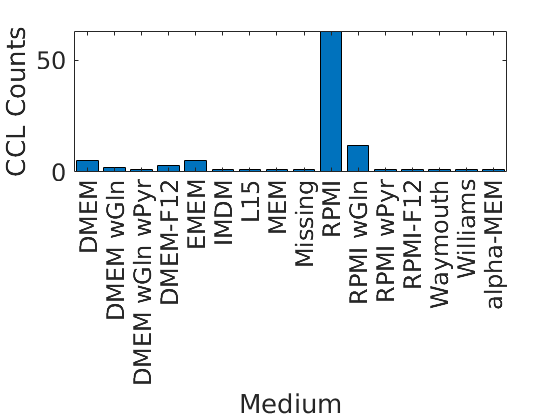

ctMedia = arrayfun(@(x) sum(tcga_meta.Media==x), uqMedia);
bar(uqMedia, ctMedia); ylabel('CCL Counts'); xlabel('Medium');

% Culture
tcga_meta.Culture = categorical(tcga_meta.Culture);
uqCulture = unique(tcga_meta.Culture); set(gca, 'fontsize', 18);

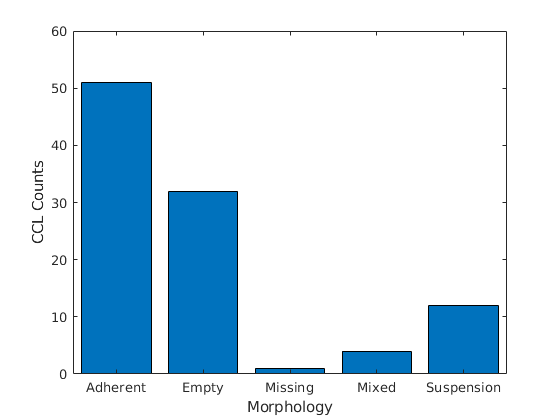

ctCulture = arrayfun(@(x) sum(tcga_meta.Culture==x), uqCulture);
bar(uqCulture, ctCulture); ylabel('CCL Counts'); xlabel('Morphology');

### Load the medium perturbation literature validation set

Literature curation from 48 medium perturbation studies and their influence on histone marker expression was used as the validation set. Note that the data consists of multiple cancer cell lines and stem cells of different lineages. 

The validation set was split into a supplementation and deprivation validation set. To reconcile potentially conflicting evidence in the literature, I used the mode to set the true class. In the event of a tie, I randomly select a class label (in the case of a tie between up/down) or set it to the non-neutral class (in the case if a tie between up/neutral or down/neutral).

The label encoding procedure was performed as follows:

- If there was **no evidence** of a nutrient perturbation and histone marker expression, the label was assigned **NaN**. This truth value and the corresponding predicted value were then removed from the classification evaluation calculations.

- If there was evidence that there was **no effect** between a nutrient perturbation and histone marker expression, the label was assigned **0** for neutral.

- If there was evidence that a nutrient perturbation **increased** histone marker levels, the label was assigned a value of **1**.

- If there was evidence that a nutrient perturbation **decreased** histone marker levels, the label was assigned a value of **-1**.

Two validation sets were considered. One validation set has all histone markers. The other validation set has 

% Get single histone modification GCP data only
MarkersToKeep = [   ...
    2, 3, 4,        ... % H3K4  me1/2/3/ac
    6, 7, 8, 9,     ... % H3K9  me1/me2/me3/ac
    21, 22, 23,     ... % H3K36 me1/me2/me3
    24, 28, 31, 33  ... % H3K27 me1/me2/me3/ac
]; 

% Filter validation data
sVal = readmatrix('~/Data/Literature/nutrient_perturbation/supplementation.csv'); sVal = sVal(:, 2:end); 
dVal = readmatrix('~/Data/Literature/nutrient_perturbation/deprivation.csv');     dVal = dVal(:, 2:end); 

### Label encoding the predicted medium perturbation GCPs 

First, the medium perturbation GCPs were classified into increased or decreased classes based on whether or not they were above or below the mean predicted value. 

thresholds = [0.05, 0.10, 0.25, 0.50, 0.75, 1.00];
for n = 1:size(lm_supplementAllGCP, 1)                       % Get each cancer cell line and store into a single variable called ccle_pred
    try                                                      % One cancer cell line is missing data
        for k = 1:size(lm_supplementAllGCP, 2)               % Get each histone marker prediction
            sYpred(:, k)       = lm_supplementAllGCP{n, k};
            dYpred(:, k)       = lm_deprivationAllGCP{n, k};
            
            sYpred_flux(:, k)  = lm_supplementFluxGCP{n, k};
            dYpred_flux(:, k)  = lm_deprivationFluxGCP{n, k};
            
            sYpred_genes(:, k) = lm_supplementGeneGCP{n, k};
            dYpred_genes(:, k) = lm_deprivationGeneGCP{n, k};
        end
        
        % First label encode if they are above / below the mean as increased (1) or decreased (-1). 
        % The decision boundary is set to the median
        sBound      = median(sYpred);       dBound      = median(dYpred);       % Entire training dataset
        sBoundFlux  = median(sYpred_flux);  dBoundFlux  = median(dYpred_flux);  % Flux only training dataset
        sBoundGenes = median(sYpred_genes); dBoundGenes = median(dYpred_genes); % Genes only training dataset
        
        % Compute percent change
        sPercent     = abs(sYpred       - cntrSet{n, 2} ./ cntrSet{n, 2}); 
        dPercent     = abs(dYpred       - cntrSet{n, 2} ./ cntrSet{n, 2});
        sFluxPercent = abs(sYpred_flux  - cntrSet{n, 2} ./ cntrSet{n, 2}); 
        dFluxPercent = abs(dYpred_flux  - cntrSet{n, 2} ./ cntrSet{n, 2});
        sGenePercent = abs(sYpred_genes - cntrSet{n, 2} ./ cntrSet{n, 2}); 
        dGenePercent = abs(dYpred_genes - cntrSet{n, 2} ./ cntrSet{n, 2});
        
        % Label encode based on the decision boundary (mean)
        sYpred(sYpred <= sBound) = -1;                  sYpred(sYpred > sBound) = 1; 
        dYpred(dYpred <= dBound) = -1;                  dYpred(dYpred > dBound) = 1;
        sYpred_flux(sYpred_flux <= sBoundFlux) = -1;    sYpred_flux(sYpred_flux > sBoundFlux) = 1; 
        dYpred_flux(dYpred_flux <= dBoundFlux) = -1;    dYpred_flux(dYpred_flux > dBoundFlux) = 1;
        sYpred_genes(sYpred_genes <= sBoundGenes) = -1; sYpred_genes(sYpred_genes > sBoundGenes) = 1; 
        dYpred_genes(dYpred_genes <= dBoundGenes) = -1; dYpred_genes(dYpred_genes > dBoundGenes) = 1;
        
        % Next, set labels to 0 if they don't cross the absolute percent change threshold.
        for p = 1:length(thresholds)
            thresh = thresholds(p);
            
            % Finish label encoding based on whether the absolute percent change crosses the
            % threshold. If not, set to 0. Otherwise, they keep their value. 
            sYpred(sPercent           <= thresh) = 0; dYpred(dPercent           <= thresh) = 0;
            sYpred_flux(sFluxPercent  <= thresh) = 0; dYpred_flux(dFluxPercent  <= thresh) = 0;
            sYpred_genes(sGenePercent <= thresh) = 0; dYpred_genes(dGenePercent <= thresh) = 0;
            
            % Save it all into a single cell array
            allSLabeled{n, p}  = sYpred;     allDLabeled{n, p}  = dYpred;     % Entire training dataset
            fluxSLabeled{n, p} = sYpred_flux; fluxDLabeled{n, p} = dYpred_flux; % Flux training dataset only
            geneSLabeled{n, p} = sYpred_genes; geneDLabeled{n, p} = dYpred_genes; % Gene training dataset only
        end
    catch ME
        warning(strcat(cntrSet{n, 1}, " is missing data. Skipping to next cancer cell line."))
        continue
    end
end

## Histone marker accuracies across 100 cancer cell lines

Next, I wanted to get a sense of how well the model performs for individual histone markers. Further, I performed a subset analysis by separating the dataset into tissue lineages, medium conditions, and cellular morphology.

### Average across all 100 cancer cell lines

thresholds = [0.05, 0.10, 0.25, 0.50, 0.75, 1.00];
for n = 1:size(allSLabeled, 1)                                                    % Each cancer cell line
    try
        for p = 1:size(allSLabeled, 2)                                            % Each threshold
            sYpred       = allSLabeled{n, p};  dYpred       = allDLabeled{n, p};  % Entire training dataset
            sYpred_flux  = fluxSLabeled{n, p}; dYpred_flux  = fluxDLabeled{n, p}; % Flux training dataset only
            sYpred_genes = geneSLabeled{n, p}; dYpred_genes = geneDLabeled{n, p}; % Gene training dataset only
            
            for q = 1:size(sYpred, 2)
                
                % Create confusion matrices for each cell line and threshold
                allHistSCM  = confusionmat(sYpred(:, q),       dVal(:, q), 'Order', [-1, 0, 1]);
                allHistDCM  = confusionmat(dYpred(:, q),       dVal(:, q), 'Order', [-1, 0, 1]);
                fluxHistSCM = confusionmat(sYpred_flux(:, q),  dVal(:, q), 'Order', [-1, 0, 1]);
                fluxHistDCM = confusionmat(dYpred_flux(:, q),  dVal(:, q), 'Order', [-1, 0, 1]);
                geneHistSCM = confusionmat(sYpred_genes(:, q), dVal(:, q), 'Order', [-1, 0, 1]);
                geneHistDCM = confusionmat(dYpred_genes(:, q), dVal(:, q), 'Order', [-1, 0, 1]); 
                
                % Compute average nutrient perturbation accuracies for each cell line and threshold
                allSHistAcc(q)  = sum(diag(allHistSCM))  / sum(allHistSCM,  'all');
                allDHistAcc(q)  = sum(diag(allHistDCM))  / sum(allHistDCM,  'all');
                fluxSHistAcc(q) = sum(diag(fluxHistSCM)) / sum(fluxHistSCM, 'all');
                fluxDHistAcc(q) = sum(diag(fluxHistDCM)) / sum(fluxHistDCM, 'all');
                geneSHistAcc(q) = sum(diag(geneHistSCM)) / sum(geneHistSCM, 'all');
                geneDHistAcc(q) = sum(diag(geneHistDCM)) / sum(geneHistDCM, 'all');
            end
            allSHistAccArr{n, p}  = allSHistAcc;   allDHistAccArr{n, p} = allDHistAcc;
            fluxSHistAccArr{n, p} = fluxSHistAcc; fluxDHistAccArr{n, p} = fluxDHistAcc;
            geneSHistAccArr{n, p} = geneSHistAcc; geneDHistAccArr{n, p} = geneDHistAcc;
        end
    catch ME
        warning(strcat(cntrSet{n, 1}, " is missing data. Skipping to next cancer cell line."))
        continue
    end
end

#### Plot the average histone accuracy

for n = 1:size(allSHistAccArr, 1)
    allSHistAcc(n, :) = allSHistAccArr{n, 1};   allDHistAcc(n, :) = allDHistAccArr{n, 1};
    fluxSHistAcc(n, :) = fluxSHistAccArr{n, 1}; fluxDHistAcc(n, :) = fluxDHistAccArr{n, 1};
    geneSHistAcc(n, :) = geneSHistAccArr{n, 1}; geneDHistAcc(n, :) = geneDHistAccArr{n, 1};
end

mask = all(isnan(allSHistAcc), 1);
marks = string(marks);
marks(mask) = [];
fluxDHistAcc(:, mask) = [];
fluxSHistAcc(:, mask) = [];
tmp = ones([100, 20]).*[1:20];

**Nutrient deprivation**

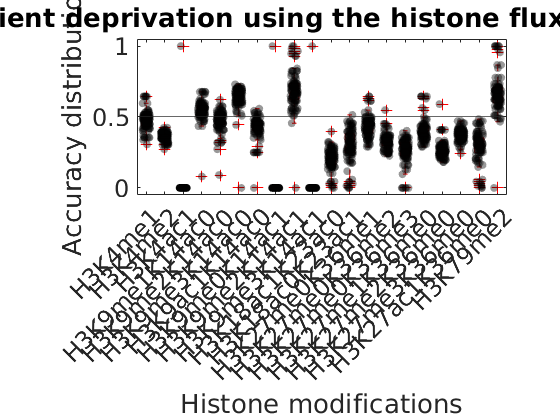

% Nutrient deprivation
boxplot(fluxDHistAcc, ...
    'Notch', 'on', 'Colors', 'r', ...
    'OutlierSize', 8, 'jitter', 0.05)
hold on;
for j = 1:length(marks)
    scatter(tmp(:, j), fluxDHistAcc(:, j), ...
        'k', 'filled', 'MarkerFaceAlpha', 0.4, ...
        'jitter', 0.05)
end
title('Nutrient deprivation using the histone flux data only', 'FontSize', 18);
xlabel('Histone modifications', 'FontSize', 18); 
ylabel('Accuracy distribution', 'FontSize', 18);
xtickangle(45); yline(0.5); set(gca, 'fontsize', 18);
xticklabels(categorical(marks))

**Nutrient supplementation**

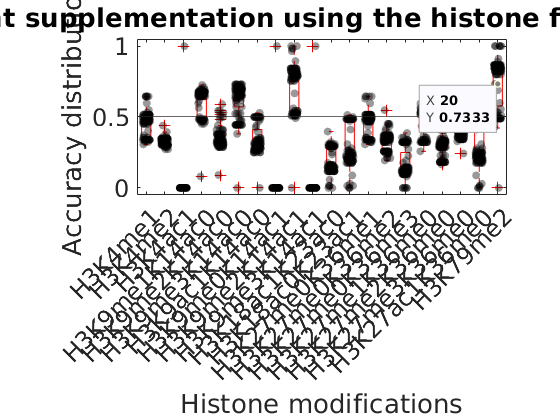

% Nutrient supplementation
boxplot(fluxSHistAcc, ...
    'Notch', 'on', 'Colors', 'r', ...
    'OutlierSize', 8, 'jitter', 0.05)
hold on;
for j = 1:length(marks)
    scatter(tmp(:, j), fluxSHistAcc(:, j), ...
        'k', 'filled', 'MarkerFaceAlpha', 0.4, ...
        'jitter', 0.05)
end

tbl = array2table(fluxSHistAcc, ...
    'RowNames', string(cntrSet(:, 1)), ...
    'VariableNames', marks);
writetable(tbl, 'supplementation_example.csv')

title('Nutrient supplementation using the histone flux data only', 'FontSize', 18);
xlabel('Histone modifications', 'FontSize', 18); 
ylabel('Accuracy distribution', 'FontSize', 18);
xtickangle(45); yline(0.5); set(gca, 'fontsize', 18);
xticklabels(categorical(marks))

### Tissue lineages

[tcga_lineages, lineage_idx] = unique(tcga_meta.Lineages);


### Medium conditions

[tcga_medium, medium_idx] = unique(tcga_meta.Media);


### Cell morphology

[tcga_morph, morph_idx] = unique(tcga_meta.Culture);


## Metabolite perturbation accuracies across 100 cancer cell lines

Additionally, I wanted to get a sense of how well the model performs for individual medium perturbations. I repeated this subset analysis by separating the dataset into tissue lineages, medium conditions, and cellular morphology.

### Average across all 100 cancer cell lines

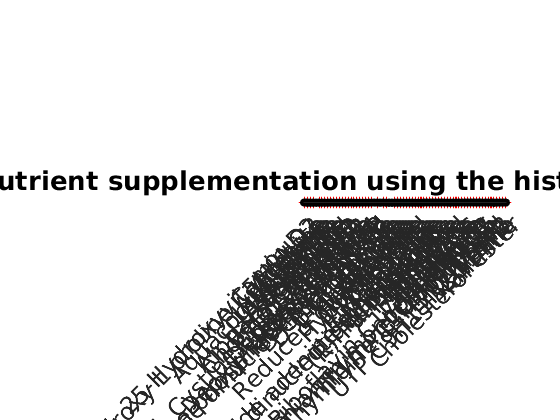

thresholds = [0.05, 0.10, 0.25, 0.50, 0.75, 1.00];
for n = 1:size(allSLabeled, 1)                                                    % Each cancer cell line
    try
        for p = 1:size(allSLabeled, 2)                                            % Each threshold
            sYpred       = allSLabeled{n, p};  dYpred       = allDLabeled{n, p};  % Entire training dataset
            sYpred_flux  = fluxSLabeled{n, p}; dYpred_flux  = fluxDLabeled{n, p}; % Flux training dataset only
            sYpred_genes = geneSLabeled{n, p}; dYpred_genes = geneDLabeled{n, p}; % Gene training dataset only
            
            for q = 1:size(sYpred, 1)
                % Create confusion matrices for each cell line and threshold
                allSCM  = confusionmat(sYpred(q, :),       dVal(q, :), 'Order', [-1, 0, 1]);
                allDCM  = confusionmat(dYpred(q, :),       dVal(q, :), 'Order', [-1, 0, 1]);
                fluxSCM = confusionmat(sYpred_flux(q, :),  dVal(q, :), 'Order', [-1, 0, 1]);
                fluxDCM = confusionmat(dYpred_flux(q, :),  dVal(q, :), 'Order', [-1, 0, 1]);

                geneSCM = confusionmat(sYpred_genes(q, :), dVal(q, :), 'Order', [-1, 0, 1]);
                geneDCM = confusionmat(dYpred_genes(q, :), dVal(q, :), 'Order', [-1, 0, 1]);
                
                % Compute average accuracies for each cell line and threshold
                allSAcc(q)  = sum(diag(allSCM))  / sum(allSCM,  'all');
                allDAcc(q)  = sum(diag(allDCM))  / sum(allDCM,  'all');
                fluxSAcc(q) = sum(diag(fluxSCM)) / sum(fluxSCM, 'all');
                fluxDAcc(q) = sum(diag(fluxDCM)) / sum(fluxDCM, 'all');
                geneSAcc(q) = sum(diag(geneSCM)) / sum(geneSCM, 'all');
                geneDAcc(q) = sum(diag(geneDCM)) / sum(geneDCM, 'all');
            end
            allSMediumAcc{n, p} = allSAcc;   allDMediumAcc{n, p} = allDAcc;
            fluxSMediumAcc{n, p} = fluxSAcc; fluxDMediumAcc{n, p} = fluxDAcc;
            geneSMediumAcc{n, p} = geneSAcc; geneDMediumAcc{n, p} = geneDAcc;
        end
    catch ME
        warning(strcat(cntrSet{n, 1}, " is missing data. Skipping to next cancer cell line."))
        continue
    end
end

Plot the average histone accuracy

for n = 1:size(allSMediumAcc, 1)
    allSAcc_medium(n, :) = allSMediumAcc{n, 1};   allDAcc_medium(n, :) = allDMediumAcc{n, 1};
    fluxSAcc_medium(n, :) = fluxSMediumAcc{n, 1}; fluxDAcc_medium(n, :) = fluxDMediumAcc{n, 1};
    geneSAcc_medium(n, :) = geneSMediumAcc{n, 1}; geneDAcc_medium(n, :) = geneDMediumAcc{n, 1};
end
tmp = ones([100, 70]).*[1:70];
load unique_nutrients.mat;

boxplot(fluxSAcc_medium, ...
    'Notch', 'on', 'Colors', 'r', ...
    'OutlierSize', 8, 'jitter', 0.05)
hold on;
for j = 1:length(allMediumComponents)
    scatter(tmp(:, j), fluxSAcc_medium(:, j), ...
        'k', 'filled', 'MarkerFaceAlpha', 0.4, ...
        'jitter', 0.05)
end
title('Nutrient supplementation using the histone flux data only', 'FontSize', 18);
xlabel('Medium perturbations', 'FontSize', 18); 
ylabel('Accuracy distribution', 'FontSize', 18);
xtickangle(45); yline(0.5); set(gca, 'fontsize', 18);
xticklabels(categorical(allMediumComponents))

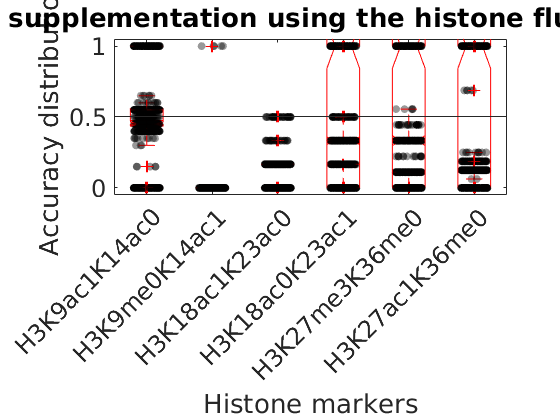

boxplot(fluxDAcc_medium, ...
    'Notch', 'on', 'Colors', 'r', ...
    'OutlierSize', 8, 'jitter', 0.05)
hold on;
for j = 1:length(allMediumComponents)
    scatter(tmp(:, j), fluxDAcc_medium(:, j), ...
        'k', 'filled', 'MarkerFaceAlpha', 0.4, ...
        'jitter', 0.05)
end
title('Nutrient Deprivation using the histone flux data only', 'FontSize', 18);
xlabel('Medium perturbations', 'FontSize', 18); 

ylabel('Accuracy distribution', 'FontSize', 18);
xtickangle(45); yline(0.5); set(gca, 'fontsize', 18);
xticklabels(categorical(allMediumComponents))

### Tissue lineages

### Medium conditions

### Cell morphology

## Specific markers

### Acetate

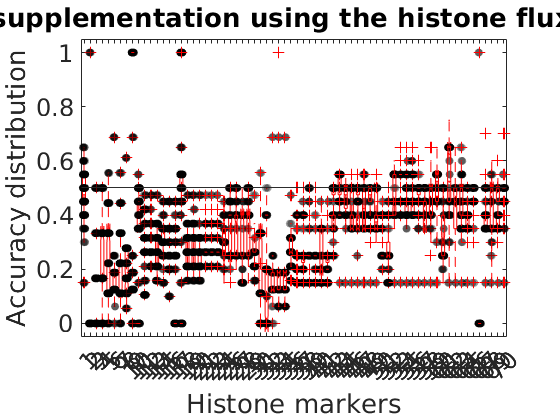

Index in position 2 exceeds array bounds (must not exceed 20).

% Acetate

for n = 1:size(allSLabeled, 1)                                                    % Each cancer cell line
    try
        sYpred       = allSLabeled{n, 1};  dYpred       = allDLabeled{n, 1};  % Entire training dataset
        sYpred_flux  = fluxSLabeled{n, 1}; dYpred_flux  = fluxDLabeled{n, 1}; % Flux training dataset only
        sYpred_genes = geneSLabeled{n, 1}; dYpred_genes = geneDLabeled{n, 1}; % Gene training dataset only
        
        for q = 1:size(sYpred, 2)
            
            % Create confusion matrices for each cell line and threshold
            allHistSCM  = confusionmat(sYpred(3, q),       dVal(3, q), 'Order', [-1, 0, 1]);
            allHistDCM  = confusionmat(dYpred(3, q),       dVal(3, q), 'Order', [-1, 0, 1]);
            fluxHistSCM = confusionmat(sYpred_flux(3, q),  dVal(3, q), 'Order', [-1, 0, 1]);
            fluxHistDCM = confusionmat(dYpred_flux(3, q),  dVal(3, q), 'Order', [-1, 0, 1]);
            geneHistSCM = confusionmat(sYpred_genes(3, q), dVal(3, q), 'Order', [-1, 0, 1]);
            geneHistDCM = confusionmat(dYpred_genes(3, q), dVal(3, q), 'Order', [-1, 0, 1]); 
            
            % Compute average nutrient perturbation accuracies for each cell line and threshold
            allSHistAcc(q)  = sum(diag(allHistSCM))  / sum(allHistSCM,  'all');
            allDHistAcc(q)  = sum(diag(allHistDCM))  / sum(allHistDCM,  'all');
            fluxSHistAcc(q) = sum(diag(fluxHistSCM)) / sum(fluxHistSCM, 'all');
            fluxDHistAcc(q) = sum(diag(fluxHistDCM)) / sum(fluxHistDCM, 'all');
            geneSHistAcc(q) = sum(diag(geneHistSCM)) / sum(geneHistSCM, 'all');
            geneDHistAcc(q) = sum(diag(geneHistDCM)) / sum(geneHistDCM, 'all');
        end
        fluxSacetateHistAccArr{n} = fluxSHistAcc; fluxDacetateHistAccArr{n} = fluxDHistAcc;
    catch ME
        warning(strcat(cntrSet{n, 1}, " is missing data. Skipping to next cancer cell line."))
        continue
    end
end

Plot the average histone accuracy for acetate

for n = 1:length(fluxSacetateHistAccArr)
    fluxSAcc_acetate(n, :) = fluxSacetateHistAccArr{n}; fluxDAcc_acetate(n, :) = fluxDacetateHistAccArr{n};
end
load CCLE_Proteomics.mat
mask = all(isnan(fluxSAcc_acetate), 1);
marks = string(marks);
marks(mask) = [];
fluxSAcc_acetate(:, mask) = [];
fluxDAcc_acetate(:, mask) = [];
tmp = ones([100, length(marks)]).*[1:length(marks)];

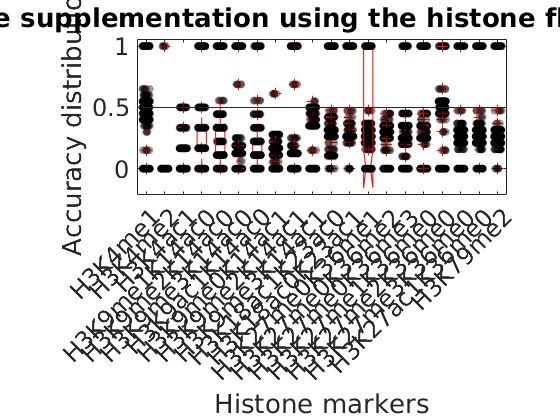

boxplot(fluxSAcc_acetate, ...
    'Notch', 'on', 'Colors', 'r', ...
    'OutlierSize', 8, 'jitter', 0.05)
hold on;
for j = 1:length(marks)
    scatter(tmp(:, j), fluxSAcc_acetate(:, j), ...
        'k', 'filled', 'MarkerFaceAlpha', 0.4, ...
        'jitter', 0.05)
end
title('Acetate supplementation using the histone flux data only', 'FontSize', 18);
xlabel('Histone markers', 'FontSize', 18); 
ylabel('Accuracy distribution', 'FontSize', 18);
xtickangle(45); yline(0.5); set(gca, 'fontsize', 18);
xticklabels(categorical(marks))

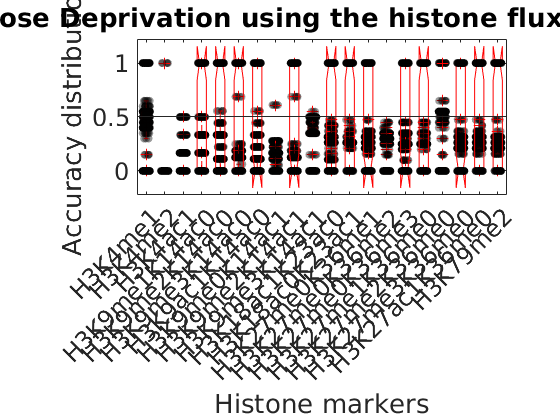

boxplot(fluxDAcc_acetate, ...
    'Notch', 'on', 'Colors', 'r', ...
    'OutlierSize', 8, 'jitter', 0.05)
hold on;
for j = 1:size(fluxDAcc_acetate, 2)
    scatter(tmp(:, j), fluxDAcc_acetate(:, j), ...
        'k', 'filled', 'MarkerFaceAlpha', 0.4, ...
        'jitter', 0.05)
end
title('Acetate Deprivation using the histone flux data only', 'FontSize', 18);
xlabel('Histone markers', 'FontSize', 18); 
ylabel('Accuracy distribution', 'FontSize', 18);
xtickangle(45); yline(0.5); set(gca, 'fontsize', 18);
xticklabels(categorical(marks))

### Glucose

% Glucose
for n = 1:size(allSLabeled, 1)                                                    % Each cancer cell line
    try
        sYpred       = allSLabeled{n, 1};  dYpred       = allDLabeled{n, 1};  % Entire training dataset
        sYpred_flux  = fluxSLabeled{n, 1}; dYpred_flux  = fluxDLabeled{n, 1}; % Flux training dataset only
        sYpred_genes = geneSLabeled{n, 1}; dYpred_genes = geneDLabeled{n, 1}; % Gene training dataset only
        
        for q = 1:size(sYpred, 2)
            
            % Create confusion matrices for each cell line and threshold
            allHistSCM  = confusionmat(sYpred(28, q),       dVal(28, q), 'Order', [-1, 0, 1]);
            allHistDCM  = confusionmat(dYpred(28, q),       dVal(28, q), 'Order', [-1, 0, 1]);
            fluxHistSCM = confusionmat(sYpred_flux(28, q),  dVal(28, q), 'Order', [-1, 0, 1]);
            fluxHistDCM = confusionmat(dYpred_flux(28, q),  dVal(28, q), 'Order', [-1, 0, 1]);
            geneHistSCM = confusionmat(sYpred_genes(28, q), dVal(28, q), 'Order', [-1, 0, 1]);
            geneHistDCM = confusionmat(dYpred_genes(28, q), dVal(28, q), 'Order', [-1, 0, 1]); 
            
            % Compute average nutrient perturbation accuracies for each cell line and threshold
            allSHistAcc(q)  = sum(diag(allHistSCM))  / sum(allHistSCM,  'all');
            allDHistAcc(q)  = sum(diag(allHistDCM))  / sum(allHistDCM,  'all');
            fluxSHistAcc(q) = sum(diag(fluxHistSCM)) / sum(fluxHistSCM, 'all');
            fluxDHistAcc(q) = sum(diag(fluxHistDCM)) / sum(fluxHistDCM, 'all');
            geneSHistAcc(q) = sum(diag(geneHistSCM)) / sum(geneHistSCM, 'all');
            geneDHistAcc(q) = sum(diag(geneHistDCM)) / sum(geneHistDCM, 'all');
        end
        fluxSglucoseHistAccArr{n} = fluxSHistAcc; fluxDglucoseHistAccArr{n} = fluxDHistAcc;
    catch ME
        warning(strcat(cntrSet{n, 1}, " is missing data. Skipping to next cancer cell line."))
        continue
    end
end

Plot the average histone accuracy for acetate

for n = 1:length(fluxSglucoseHistAccArr)
    fluxSAcc_glucose(n, :) = fluxSglucoseHistAccArr{n}; fluxDAcc_glucose(n, :) = fluxDglucoseHistAccArr{n};
end
load CCLE_Proteomics.mat
mask = all(isnan(fluxSAcc_glucose), 1);
marks = string(marks);
marks(mask) = [];
fluxSAcc_glucose(:, mask) = [];
fluxDAcc_glucose(:, mask) = [];
tmp = ones([100, length(marks)]).*[1:length(marks)];

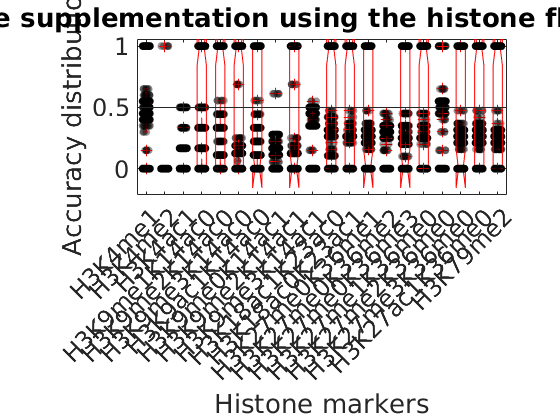

boxplot(fluxSAcc_glucose, ...
    'Notch', 'on', 'Colors', 'r', ...
    'OutlierSize', 8, 'jitter', 0.05)
hold on;
for j = 1:length(marks)
    scatter(tmp(:, j), fluxSAcc_glucose(:, j), ...
        'k', 'filled', 'MarkerFaceAlpha', 0.4, ...
        'jitter', 0.05)
end
title('Glucose supplementation using the histone flux data only', 'FontSize', 18);
xlabel('Histone markers', 'FontSize', 18); 
ylabel('Accuracy distribution', 'FontSize', 18);
xtickangle(45); yline(0.5); set(gca, 'fontsize', 18);
xticklabels(categorical(marks))

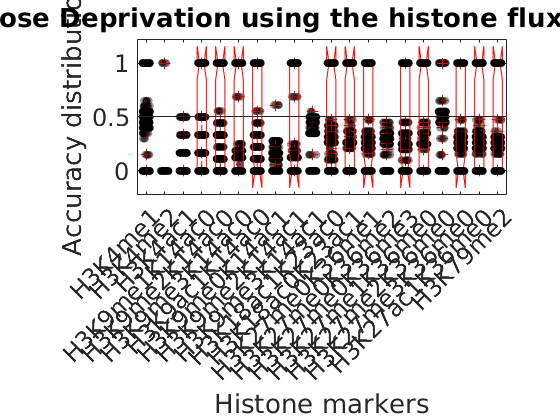

boxplot(fluxDAcc_glucose, ...
    'Notch', 'on', 'Colors', 'r', ...
    'OutlierSize', 8, 'jitter', 0.05)
hold on;
for j = 1:size(fluxDAcc_glucose, 2)
    scatter(tmp(:, j), fluxDAcc_glucose(:, j), ...
        'k', 'filled', 'MarkerFaceAlpha', 0.4, ...
        'jitter', 0.05)
end
title('Glucose Deprivation using the histone flux data only', 'FontSize', 18);
xlabel('Histone markers', 'FontSize', 18); 
ylabel('Accuracy distribution', 'FontSize', 18);
xtickangle(45); yline(0.5); set(gca, 'fontsize', 18);
xticklabels(categorical(marks))

### Folate

% Folate
for n = 1:size(allSLabeled, 1)                                                    % Each cancer cell line
    try
        sYpred       = allSLabeled{n, 1};  dYpred       = allDLabeled{n, 1};  % Entire training dataset
        sYpred_flux  = fluxSLabeled{n, 1}; dYpred_flux  = fluxDLabeled{n, 1}; % Flux training dataset only
        sYpred_genes = geneSLabeled{n, 1}; dYpred_genes = geneDLabeled{n, 1}; % Gene training dataset only
        
        for q = 1:size(sYpred, 2)
            
            % Create confusion matrices for each cell line and threshold
            allHistSCM  = confusionmat(sYpred(28, q),       dVal(28, q), 'Order', [-1, 0, 1]);
            allHistDCM  = confusionmat(dYpred(28, q),       dVal(28, q), 'Order', [-1, 0, 1]);
            fluxHistSCM = confusionmat(sYpred_flux(28, q),  dVal(28, q), 'Order', [-1, 0, 1]);
            fluxHistDCM = confusionmat(dYpred_flux(28, q),  dVal(28, q), 'Order', [-1, 0, 1]);
            geneHistSCM = confusionmat(sYpred_genes(28, q), dVal(28, q), 'Order', [-1, 0, 1]);
            geneHistDCM = confusionmat(dYpred_genes(28, q), dVal(28, q), 'Order', [-1, 0, 1]); 
            
            % Compute average nutrient perturbation accuracies for each cell line and threshold
            allSHistAcc(q)  = sum(diag(allHistSCM))  / sum(allHistSCM,  'all');
            allDHistAcc(q)  = sum(diag(allHistDCM))  / sum(allHistDCM,  'all');
            fluxSHistAcc(q) = sum(diag(fluxHistSCM)) / sum(fluxHistSCM, 'all');
            fluxDHistAcc(q) = sum(diag(fluxHistDCM)) / sum(fluxHistDCM, 'all');
            geneSHistAcc(q) = sum(diag(geneHistSCM)) / sum(geneHistSCM, 'all');
            geneDHistAcc(q) = sum(diag(geneHistDCM)) / sum(geneHistDCM, 'all');
        end
        fluxSfolateHistAccArr{n} = fluxSHistAcc; fluxDfolateHistAccArr{n} = fluxDHistAcc;
    catch ME
        warning(strcat(cntrSet{n, 1}, " is missing data. Skipping to next cancer cell line."))
        continue
    end
end

Plot the average histone accuracy for acetate

for n = 1:length(fluxSfolateHistAccArr)
    fluxSAcc_folate(n, :) = fluxSfolateHistAccArr{n}; fluxDAcc_folate(n, :) = fluxDfolateHistAccArr{n};
end
load CCLE_Proteomics.mat
mask = all(isnan(fluxSAcc_folate), 1);
marks = string(marks);
marks(mask) = [];
fluxSAcc_folate(:, mask) = [];
fluxDAcc_folate(:, mask) = [];
tmp = ones([100, length(marks)]).*[1:length(marks)];

boxplot(fluxSAcc_folate, ...
    'Notch', 'on', 'Colors', 'r', ...
    'OutlierSize', 8, 'jitter', 0.05)
hold on;
for j = 1:length(marks)
    scatter(tmp(:, j), fluxSAcc_folate(:, j), ...
        'k', 'filled', 'MarkerFaceAlpha', 0.4, ...
        'jitter', 0.05)
end
title('Folate supplementation using the histone flux data only', 'FontSize', 18);
xlabel('Histone markers', 'FontSize', 18); 
ylabel('Accuracy distribution', 'FontSize', 18);
xtickangle(45); yline(0.5); set(gca, 'fontsize', 18);
xticklabels(categorical(marks))

boxplot(fluxDAcc_folate, ...
    'Notch', 'on', 'Colors', 'r', ...
    'OutlierSize', 8, 'jitter', 0.05)
hold on;
for j = 1:size(fluxDAcc_folate, 2)
    scatter(tmp(:, j), fluxDAcc_folate(:, j), ...
        'k', 'filled', 'MarkerFaceAlpha', 0.4, ...
        'jitter', 0.05)
end
title('Folate Deprivation using the histone flux data only', 'FontSize', 18);
xlabel('Histone markers', 'FontSize', 18); 
ylabel('Accuracy distribution', 'FontSize', 18);
xtickangle(45); yline(0.5); set(gca, 'fontsize', 18);
xticklabels(categorical(marks))

## Random permutation between the training and true labels

This module computes the random permutation accuracy between the predicted supplementation and deprivation labels from different thresholds and the true labels from the medium perturbation literature curation. 

iters = 1;                                                                                    % Number of random permutation between predicted
for n = 1:size(allSLabeled, 1)                                                                % Each cancer cell line
    try
        for p = 1:size(allSLabeled, 2)                                                        % Each threshold
            sYpred       = allSLabeled{n, p};  dYpred       = allDLabeled{n, p};              % Entire training dataset
            sYpred_flux  = fluxSLabeled{n, p}; dYpred_flux  = fluxDLabeled{n, p};             % Flux training dataset only
            sYpred_genes = geneSLabeled{n, p}; dYpred_genes = geneDLabeled{n, p};             % Gene training dataset only
        
            for i = 1:size(sVal, 2)    % Run a permutation test for each histone marker
                sGuess(:, i)     = permutationGuess(sYpred(:, i),       sVal(:, i), iters); 
                dGuess(:, i)     = permutationGuess(dYpred(:, i),       dVal(:, i), iters);
                sFluxGuess(:, i) = permutationGuess(sYpred_flux(:, i),  sVal(:, i), iters); 
                dFluxGuess(:, i) = permutationGuess(dYpred_flux(:, i),  dVal(:, i), iters);
                sGeneGuess(:, i) = permutationGuess(sYpred_genes(:, i), sVal(:, i), iters); 
                dGeneGuess(:, i) = permutationGuess(sYpred_genes(:, i), dVal(:, i), iters);
            end
                        % Create confusion matrices for each cell line and threshold
            allSCM  = confusionmat(sYpred(:),       dVal(:), 'Order', [-1, 0, 1]);
            allDCM  = confusionmat(dYpred(:),       dVal(:), 'Order', [-1, 0, 1]);
            fluxSCM = confusionmat(sYpred_flux(:),  dVal(:), 'Order', [-1, 0, 1]);
            fluxDCM = confusionmat(dYpred_flux(:),  dVal(:), 'Order', [-1, 0, 1]);
            geneSCM = confusionmat(sYpred_genes(:), dVal(:), 'Order', [-1, 0, 1]);
            geneDCM = confusionmat(dYpred_genes(:), dVal(:), 'Order', [-1, 0, 1]);
            
            % Compute average accuracies for each cell line and threshold
            allPertSAcc(n, p)  = sum(diag(allSCM))  / sum(allSCM,  'all');
            allPertDAcc(n, p)  = sum(diag(allDCM))  / sum(allDCM,  'all');
            fluxPertSAcc(n, p) = sum(diag(fluxSCM)) / sum(fluxSCM, 'all');
            fluxPertDAcc(n, p) = sum(diag(fluxDCM)) / sum(fluxDCM, 'all');
            genePertSAcc(n, p) = sum(diag(geneSCM)) / sum(geneSCM, 'all');
            genePertDAcc(n, p) = sum(diag(geneDCM)) / sum(geneDCM, 'all');
            
            % See if the average accuracy is statistically significant against random chance
            [allSHyp(n, p),  allSPvalue(n, p)]  = ttest2(allPertSAcc(n, p),  sGuess(:));
            [allDHyp(n, p),  allDPvalue(n, p)]  = ttest2(allPertDAcc(n, p),  dGuess(:));
            [fluxSHyp(n, p), fluxSPvalue(n, p)] = ttest2(fluxPertSAcc(n, p), sFluxGuess(:));
            [fluxDHyp(n, p), fluxDPvalue(n, p)] = ttest2(fluxPertDAcc(n, p), dFluxGuess(:));
            [geneSHyp(n, p), geneSPvalue(n, p)] = ttest2(genePertSAcc(n, p), sGeneGuess(:));
            [geneDHyp(n, p), geneDPvalue(n, p)] = ttest2(genePertDAcc(n, p), dGeneGuess(:));
        end
    catch ME
        warning(strcat(cntrSet{n, 1}, " is missing data. Skipping to next cancer cell line."))
        continue
    end
end

## Evaluate model performance

### Heatmap of average accuracies for different thresholds and different experiments

This visualization exercise will show the best thresholds to use for analyzing the dataset and which experiments to use. The heatmaps show that the highest average accuracy is for the flux supplementation and deprvation experiments using 25%  change threshold.

% Edit the colormap to make more continuous
redbluecmap = imresize(redbluecmap, [1000, 3]); redbluecmap = min(max(redbluecmap, 0), 1);
tcga_ccl{64} = 'Missing';
% Average accuracy using the entire supplementary training dataset using different threshold values
heatmap(allPertSAcc, 'colormap', redbluecmap, ...
    'XData', {'5%', '10%', '25%', '50%', '75%', '100%'}, 'YData', tcga_ccl, ...
    'Title', 'Average accuracy using the entire supplementary training dataset', ...
    'XLabel', 'Thresholds', 'YLabel', 'Cancer cell lines');
mean(allPertSAcc)

% Average accuracy using the entire deprivation training dataset using different threshold values
heatmap(allPertDAcc, 'colormap', redbluecmap, ...
    'XData', {'5%', '10%', '25%', '50%', '75%', '100%'}, 'YData', tcga_ccl, ...
    'Title', 'Average accuracy using the entire deprivation training dataset', ...
    'XLabel', 'Thresholds', 'YLabel', 'Cancer cell lines');
mean(allPertDAcc)

% Average accuracy using the flux supplementary training dataset using different threshold values
heatmap(fluxPertSAcc, 'colormap', redbluecmap, ...
    'XData', {'5%', '10%', '25%', '50%', '75%', '100%'},'YData', tcga_ccl, ...
    'Title', 'Average accuracy using the flux supplementary training dataset', ...
    'XLabel', 'Thresholds', 'YLabel', 'Cancer cell lines');
mean(fluxPertSAcc)

% Average accuracy using the flux deprivation training dataset using different threshold values
heatmap(fluxPertDAcc, 'colormap', redbluecmap, ...
    'XData', {'5%', '10%', '25%', '50%', '75%', '100%'}, 'YData', tcga_ccl, ...
    'Title', 'Average accuracy using the flux deprivation training dataset', ...
    'XLabel', 'Thresholds', 'YLabel', 'Cancer cell lines');
mean(fluxPertDAcc)

% Average accuracy using the gene expression training dataset using different threshold values
heatmap(genePertDAcc, 'colormap', redbluecmap, ...
    'XData', {'5%', '10%', '25%', '50%', '75%', '100%'}, 'YData', tcga_ccl, ...
    'Title', 'Average accuracy using the gene training dataset', ...
    'XLabel', 'Thresholds', 'YLabel', 'Cancer cell lines');
mean(genePertDAcc)

### Examine lung tissue lineage with the flux only experiments

lungIdx = string(tcga_meta.Lineage) == 'Lung'


### Confusion matrices

The confusion matrices are normalized to reflect the accuracy or error rate for each class. The **row summaries** display the **recall** for each class. The **column summaries** display the **precision** for each class. 

idx = (fluxSAcc==max(fluxSAcc, [], 'all'))
finalcm  = fluxSCM{idx};
tcga_ccl = string(tcga_ccl);
ccl      = tcga_ccl(logical(sum(idx, 2)));
meta     = tcga_meta(logical(sum(idx, 2)), :)
% Confusion matrices
figure;
confusionchart(finalcm, ...
    'Normalization', 'total-normalized', ...
    'RowSummary',    'row-normalized', ...
    'ColumnSummary', 'column-normalized')

### Plot which markers are correctly / incorrectly labeled for each experiment

Using the entire training dataset and setting the threshold to 5% change between the medium perturbation (both supplementation and deprivation) and WT, the models do pick up the low hanging fruit for markers that are commonly studied, including H3K4, H3K9, H3K27, and H3K36 (the only exception was H3K9me2K14ac1). 

The model also predicts single histone modifications better than mixed modifications (ie K27 or K36 modifications separately, not H3K27 and K36 together). 

load mediumPerturbation.mat;
[~, ~, marks, ~] = load_proteomics('CCLE');
mediumExpts = sort(mediumPerturbationIDs(:, 1));

% Find row and col position, and get related experiment / threshold 
tmp = double(idx); col = sum(tmp); row = sum(tmp, 2);
colPos = find(col == 1); rowPos = find(row == 1);
if (sum(rowPos) > 1)
    rowPos(end) = 0;
    rowPos(end) = [];
end
if colPos < 6
    if mod(colPos, 2) == 0
        tmp(rowPos, colPos-1) = 1;
    else
        tmp(rowPos, colPos+1) = 1;
    end
else
    tmp(rowPos, colPos-1) = 1;
end
idx = logical(tmp)
% Set variables to display
bestPerformingData = finalLabelData(idx);

depr = bestPerformingData{2};            % Deprivation
d = dVal; wrong_depr = (depr ~= dVal);
d(wrong_depr) = -2; 

supp = bestPerformingData{1};            % Supplementation
s = sVal; wrong_supp = (supp ~= sVal);
s(wrong_supp) = -2;
    
% Set figure properties
cmap = [...                                                  % Adjust color map / color bar / color encoding
    [0.00, 0.00, 0.00]; ...                                  % Black -> NaN  -> Incorrect
    [0.00, 0.50, 1.00]; ...                                  % Blue  -> -1   -> Decreased
    [0.63, 0.63, 0.63]; ...                                  % Gray  ->  0   -> Neutral
    [1.00, 0.00, 0.00]  ...                                  % Red   ->  1   -> Increased
];
performanceTitle = titles(idx);                              % Plot heatmaps showing prediction v validation set           
xlabels = marks; ylabels = mediumExpts;                      % Labeling

% Supplement figure
figure; sax = imagesc(s); title(performanceTitle(1)); 
k = sax.Parent; k.Parent.Position = [360, 198, 1000, 1000];  % Plot appropriate size in livescript
colormap(cmap); xtickangle(90);
colorbar('Ticks', [-2, -1, 0, 1], ...
         'TickLabels', {'Incorrect', 'Decrease', ...
                        'Neutral', 'Increase'});

set(gca, ...
    'XTick', 1:length(xlabels), 'XTickLabel', xlabels, ...
    'YTick', 1:length(ylabels), 'YTickLabel', ylabels ...
);
% Deprivation figure
figure; dax = imagesc(d); title(performanceTitle(2)); 
k = dax.Parent; k.Parent.Position = [360, 198, 1000, 1000];  % Plot appropriate size in livescript
colormap(cmap); xtickangle(90);
colorbar('Ticks', [-2, -1, 0, 1], ...
         'TickLabels', {'Incorrect', 'Decrease', ...
                        'Neutral', 'Increase'} ...
);
set(gca, ...
    'XTick', 1:length(xlabels), 'XTickLabel', xlabels, ...
    'YTick', 1:length(ylabels), 'YTickLabel', ylabels ...
);